## 载波传输 BPSK

#### 参数设置

clearvars;
close all;
clc;
rng(2023);  %固定随机种子，保证结果可复现

% 脉冲成形波形参数
T = 0.01; % 周期
V = 1/sqrt(T); % 幅度

%载波参数
f_c=500; %载波频率

% 噪声的单边功率谱密度
n0 = 0.5;


% 最小时间间隔
delta_t = 1e-4;

% 符号个数
N = 1e5;

% 符号能量
Es = 1;%不知道要我咋算，我就自己取个1了 

%仿真时间
t = (delta_t:delta_t:N*T);

%每个符号周期采样次数
num=T/delta_t;

#### 储存数组

% 成形脉冲
p_t = V * ones(num,1);

%初始化接收符号、判决符号
y=zeros(1,N);
x_hat=zeros(1,N);

%基带脉冲成形
x0_t=zeros(1,N*num);

%随机生成符号序列
bit_data = randi([0 1], 1, N);
 % 转化为调制后的电平序列（mod_data）
mod_data = my_gray_map_real_M2(bit_data);

#### 传输过程

% 加性噪声
noise_power = n0/(2*delta_t);
noise = sqrt(noise_power) * randn(size(t));

%脉冲成形
for cnt = 1:N   
    x0_t(num*(cnt-1)+1:num*cnt) = mod_data(cnt)*p_t;
end
%BPSK调制
x_t = x0_t.*(sqrt(2)*cos(2*pi*f_c*t));
% AWGN信道
y_t = x_t + noise;


% 最佳接收及判决结果
for cnt=1:N
    t_0=num*(cnt-1)+1:num*cnt;
    current=y_t(t_0);
    carrier=sqrt(2)*cos(2*pi*f_c*t_0*delta_t);
    y(cnt)=10*sum(current.*carrier)*delta_t;    
end
x_hat=my_inverse_gray_map_real_M2(y);


% 差错比特
bit_err = xor(x_hat,bit_data);
% 计算差错比特数
ber = sum(bit_err);
ser=ber;

% 归一化
ser = ser/N;
ber = ber/N;

ser_theory=qfunc(sqrt(2*Es/n0));
ber_theory=ser_theory;

#### 绘图

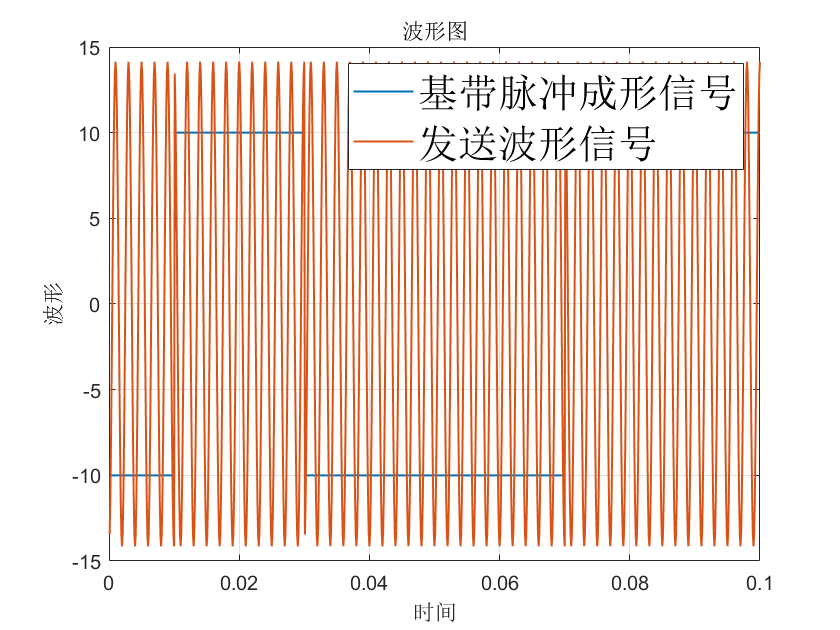

figure;
plot((delta_t:delta_t:10*T)', x0_t(1:10*num), ...
        'LineWidth', 1);
hold on
plot((delta_t:delta_t:10*T)', x_t(1:10*num), ...
        'LineWidth', 1);
xlabel('时间');
ylabel('波形');
title('波形图');
box on;
grid on;
legend('基带脉冲成形信号','发送波形信号','fontsize',20);

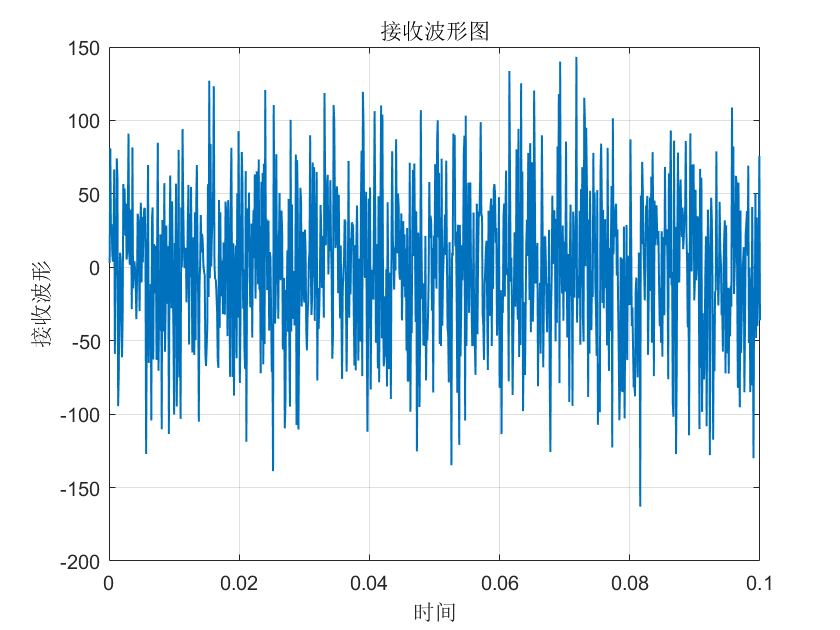


figure;
plot((+delta_t:delta_t:10*T)', y_t(1:10*num), ...
        'LineWidth', 1);
xlabel('时间');
ylabel('接收波形');
title('接收波形图');
box on;
grid on;

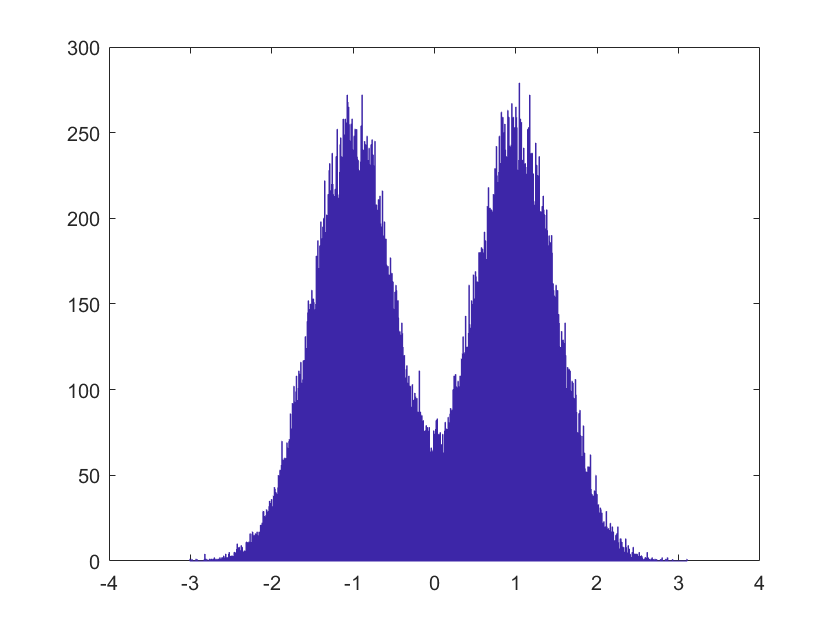


figure;
%y的统计分布
hist(y,1e3)

### 改变噪声功率谱密度并绘图

% 噪声的单边功率谱密度（新的）
tmp1=[0.1:0.02:5];
tmp2=[6:1:50];
n00 = [tmp1,tmp2];

ser_theory_00=zeros(size(n00));
ser_00=zeros(size(n00));

for n=1:length(n00)

% 加性噪声
noise_power_00 = n00(n)/(2*delta_t);
noise_00 = sqrt(noise_power_00) * randn(size(t));
% AWGN信道
y_t = x_t + noise_00;


% 最佳接收及判决结果
for cnt=1:N
    t_0=num*(cnt-1)+1:num*cnt;
    current=y_t(t_0);
    carrier=sqrt(2)*cos(2*pi*f_c*t_0*delta_t);
    y(cnt)=10*sum(current.*carrier)*delta_t;    
end
x_hat=my_inverse_gray_map_real_M2(y);


% 差错比特
bit_err = xor(x_hat,bit_data);
% 计算差错比特数
ser_00(n) = sum(bit_err);


% 归一化
ser_00(n) = ser_00(n)/N;
ser_theory_00(n)=qfunc(sqrt(2*Es/n00(n)));

end



#### 绘图

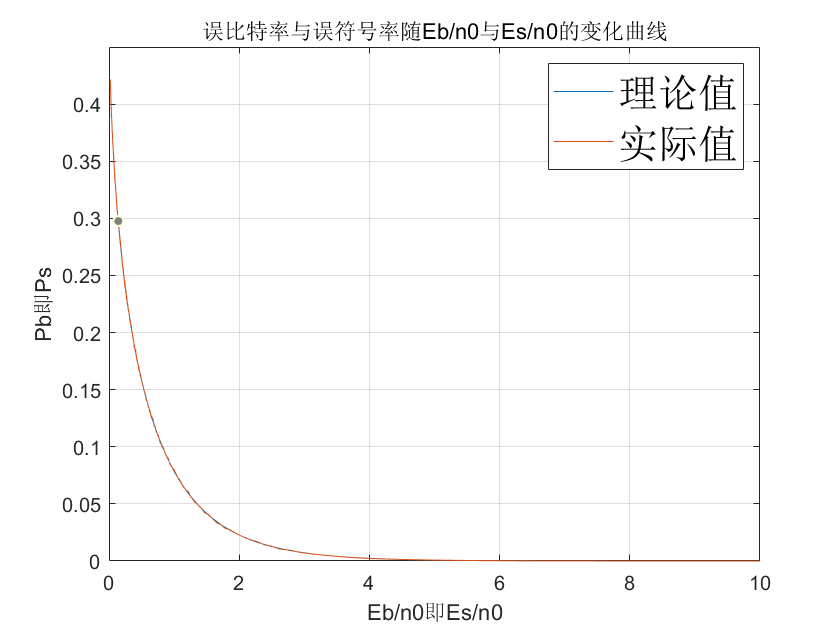

figure;
plot(Es./n00,ser_theory_00);
hold on;
plot(Es./n00,ser_00);
xlabel('Eb/n0即Es/n0');
ylabel('Pb即Ps');
title('误比特率与误符号率随Eb/n0与Es/n0的变化曲线');


box on;
grid on;
legend('理论值','实际值','fontsize',20);


### 自定义函数

M=2，由bit序列映射到电平符号

function mod_data = my_gray_map_real_M2(bit_data)
% 对应的符号序列长度
N = length(bit_data);
mod_data = zeros(1,N);
Es=1;%要不然会报错，我写在这里
% 逐个符号判断映射关系(0:-A ; 1:A)
for n = 1:N
    current_bits = bit_data(n);
    if current_bits == 0
        mod_data(n)=-sqrt(Es);
    elseif current_bits == 1
        mod_data(n)=sqrt(Es);
    end
end
end

M=2，由电平符号映射到bit序列

function demod_bit_data = my_inverse_gray_map_real_M2(rx_data)
% 符号序列长度
N = length(rx_data);
demod_bit_data = zeros(1,N);
% 逐个符号判决
for n = 1:N
    current_level = rx_data(n);
    if current_level < 0
        demod_bit_data(n)=0;
    elseif current_level >= 0
        demod_bit_data(n)=1;
    end 
end
end